# CCLE GCP-Metabolomics Correlation Analysis

**Author:** Scott Campit

## Summary

This script computes the correlation between the raw CCLE metabolomics data and ratios of histone markers. Observations are made through various biological lenses.

**Updates:**

*10/14/2020*

- Added sanity checks, heatmaps, and subset analyses with notable observations.

- Data is saved as MATLAB .mat files for faster access.

## Load and filter datasets

First, we'll load the data from Excel sheets.

clear all;
metabolomics_path = '~/Data/Metabolomics/CCLE/CCLE metabolomics dataset.xlsx';
metabolomics_sheet = 'All';

gcp_path = '~/Data/Proteomics/CCLE/CCLE Global Chromatin Profiles.xlsx';
gcp_sheet = 'All';

% First we need to clean up the metabolomics dataset
metabolomics = readtable(metabolomics_path, 'sheet', metabolomics_sheet);

gcp = readtable(gcp_path, 'sheet', gcp_sheet);

Next, we'll get matching cell line data between the two datasets.

[~, ia, ib] = intersect(string(table2cell(metabolomics(:, 'CCL'))), ...
                        string(table2cell(gcp(:, 'CellLine'))));
                    
% Finally, let's get tables with matching indicies
metabolomics = metabolomics(ia, :);
gcp = gcp(ib, :);

Let's also store some useful meta-data in a separate table.

meta = metabolomics(:, 2:4);
metabolomics(:, 2:4) = [];

For quick references, I'll save these tables as a structure for downstream analyses.

epimet.Name = "Mapped out metabolomics and GCP data from the CCLE";
epimet.Author = "Scott Campit";
epimet.LastEdited = "10/14/2020";
epimet.README = "gcp: Histone global chromatin profiles" + newline + ...
                "metabolomics: Metabolomics data" + newline + ...
                "meta: Cell line metadata";
epimet.gcp = gcp;
epimet.metabolomics = metabolomics;
epimet.meta = meta;

Let's save this data.

epimet_path = '~/Analysis/eGEMM/epimet.mat';
save(epimet_path, 'epimet');

## Global correlations between GCPs and metabolomics

This code block computes Pearson Correlation Coefficients (PCCs) between GCPs and metabolomics data.

### Data Preprocessing

First, transform the data from cell data type to numerical

gcp_mat = table2array(gcp(:, 2:end));
met_mat = table2array(metabolomics(:, 2:end));

Let's grab metabolite and GCP labels while we're at it.

gcp_labels = string(gcp.Properties.VariableNames(2:end));
met_labels = string(metabolomics.Properties.VariableNames(2:end));

We have to also set NaNs to some value. I'll use KNN imputation.

gcp_mat = knnimpute(gcp_mat);
met_mat = knnimpute(met_mat);

### SANITY CHECK: GCP AND METABOLOMICS DISTRIBUTION

As a sanity check, let's plot the distributions. I'm looking for the distributions to be Gaussian. While the data have different median values, they are Gaussian in shape, and I think our normality assumptions will hold when computing PCCs.

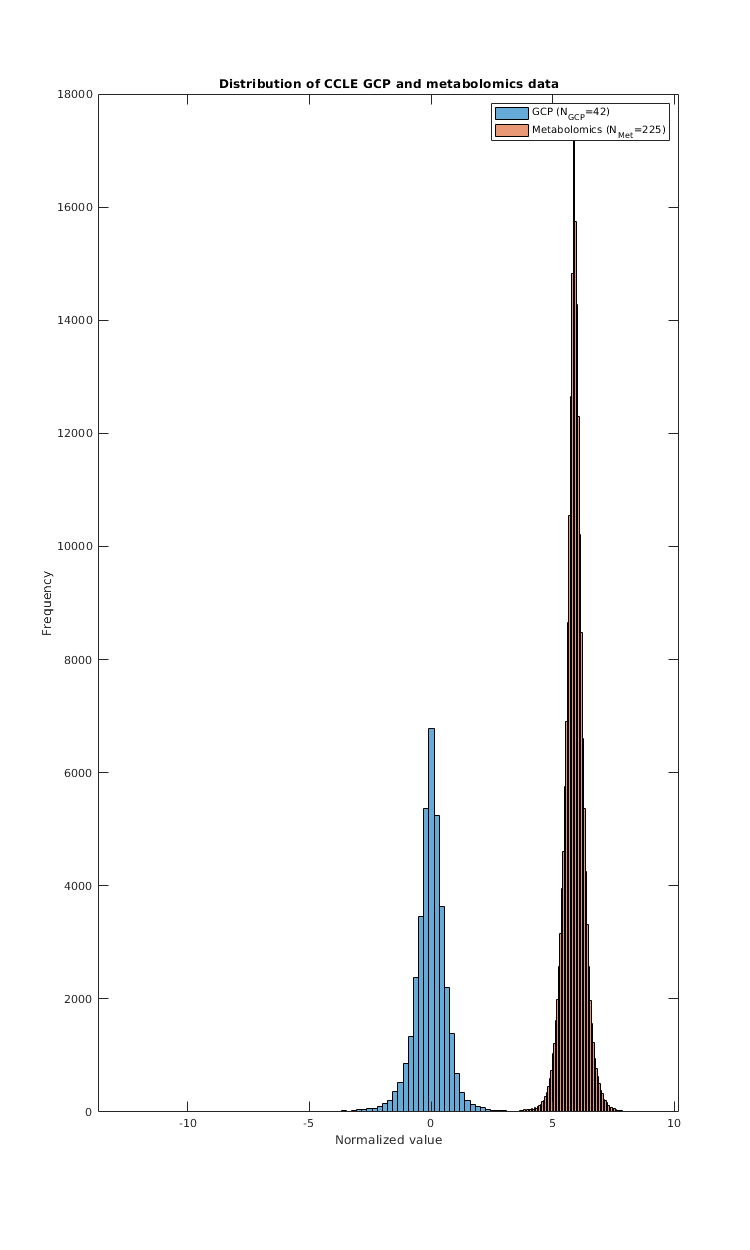

histogram(gcp_mat, 100);
hold on;
histogram(met_mat, 100);
hold off;
legend('GCP (N_{GCP}=42)', 'Metabolomics (N_{Met}=225)');
xlabel('Normalized value');
ylabel('Frequency');
title('Distribution of CCLE GCP and metabolomics data');

Finally, let's compute the final correlation.

[pcc, pval] = corr(gcp_mat, met_mat);

Let's save this data as a structure to access later.

epimetcorr.Name = "Epigenetics-Metabolism Correlation Analysis";
epimetcorr.Author = "Scott Campit";
epimetcorr.LastEdited = "10/14/2020";
epimetcorr.README = "pcc_all: PCC (entire dataset)" + newline + ...
                    "pval_all: P-values (entire dataset)" + newline + ...
                    "pcc_acme: PCC (acetyl/methylation dataset)" + newline + ...
                    "pval_acme: P-values (acetyl/methylation dataset)";
epimetcorr.pcc_all  = pcc;
epimetcorr.pval_all = pval;

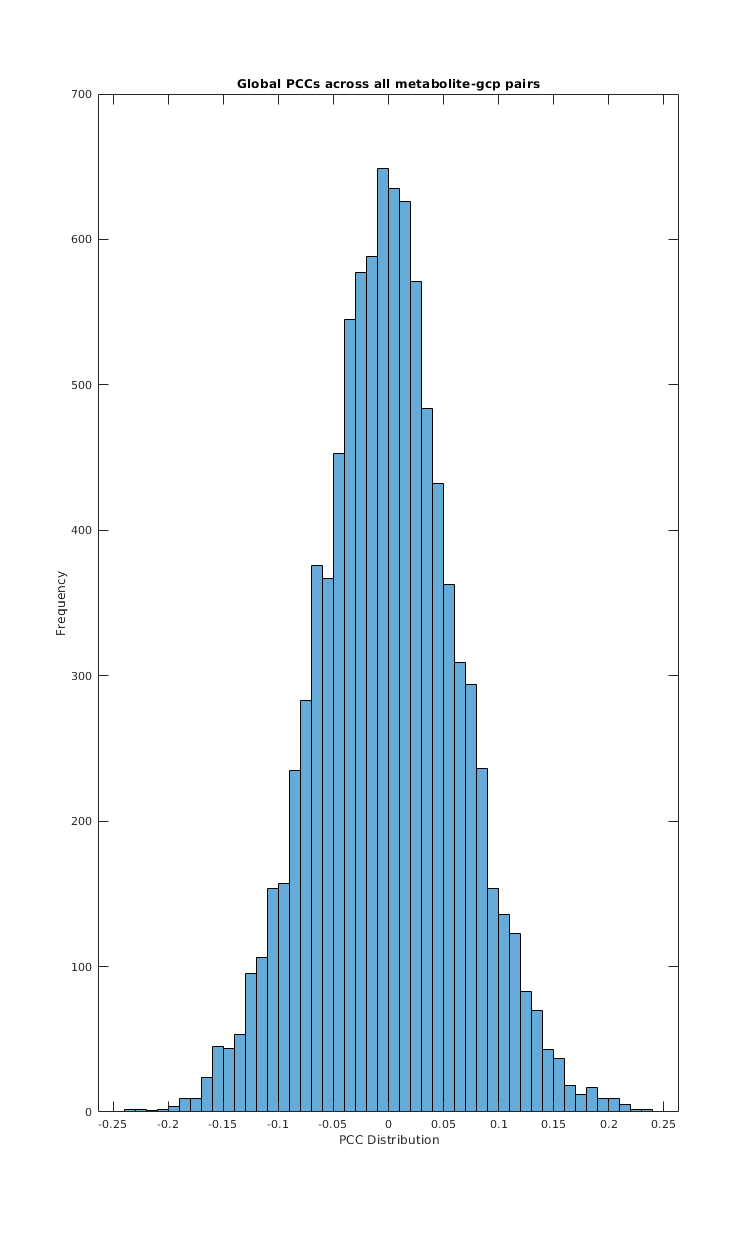

histogram(pcc);
xlabel('PCC Distribution');
ylabel('Frequency');
title("Global PCCs across all metabolite-gcp pairs");

We're not interested in correlations that are non-significant. Let's set those to NaN.

mask = (pval > 0.05);
pcc_masked = pcc;
pcc_masked(mask) = NaN;
pval_masked = pval;

If they are all NaN, that's also not interesting to us.

To simplify our analyses, we are also only interested in single-modifications. So we'll only analyze those.

single_mods = [2, 3, 4, ...         % H3K4 me1, me2, ac1
               6, 7, 8, 9, ...      % H3K9 me1, me2, me3, ac1
               10, ...              % H3K14 ac1
               16, 17, ...          % H3K18 ac1, H3K23 ac1
               21, 22, 23, ...      % H3K36 me1, me2, me3
               24, 28, 31, 33, ...  % H3K27 me1, me2, me3, ac1
               41, 42];             % H3K79 me1, me2
pcc_masked = pcc_masked(single_mods, :);
pval_masked = pval(single_mods, :);
gcp_labels = gcp_labels(single_mods);

## PCC Heatmaps

This code block visualizes the correlation matrix as a heatmap for single histone modifications and all metabolites. We'll visualize fatty acids and polar metabolites separately to simplify our analysis.

First, let's clean up our labels for the metabolites

met_labels = strrep(met_labels, '-', ' ');
met_labels = strrep(met_labels, '_', ' ');

### Polar metabolite correlation heatmap

From this analysis, it is hard to determine how polar metabolites and GCPs are related to each other. I will partition out the dataset in subsequent steps below.

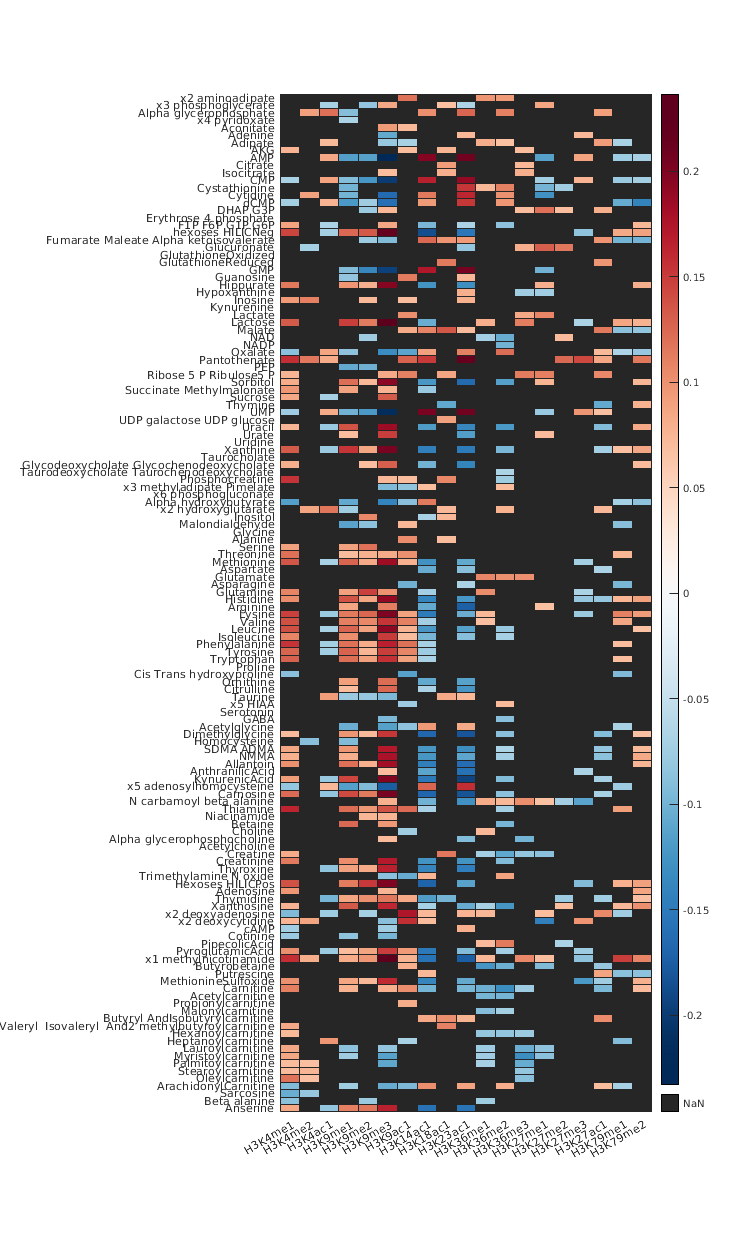

% Heatmap
redbluecmap = imresize(redbluecmap, [1000, 3]); 
redbluecmap = min(max(redbluecmap, 0), 1);
figure;
hm_obj = pcc_masked';
hm_obj = hm_obj(1:136, :);
heatmap(hm_obj, ...
        'colormap', redbluecmap, ...
        'XData', gcp_labels, ...
        'YData', met_labels(1:136));
set(findall(gcf,'-property','FontSize'),'FontSize',10);
set(gcf,'position',[0,0,750,1250]);

### Lipid correlation heatmap

From this analysis, here are some interesting observations:

- DAG and PC metabolites are positively correlated with acetylation markers, while having a negative correlation with H3K9 methylation markers

- TAGs with 46-50 carbon molecules show a positive relationship with H3K14ac and H3K23ac, but then become non significant after 52 carbons. Additionally, H3K9ac becomes negatively correlated with longer chain TAGs.

- Ceramides are positively correlated with several histone methylatoin markers of various methylation statuses, with the strongest relationship between H3K9me3. Additionally, there's negative correlations with histone acetylation, specifically H3K14ac and H3K23ac.

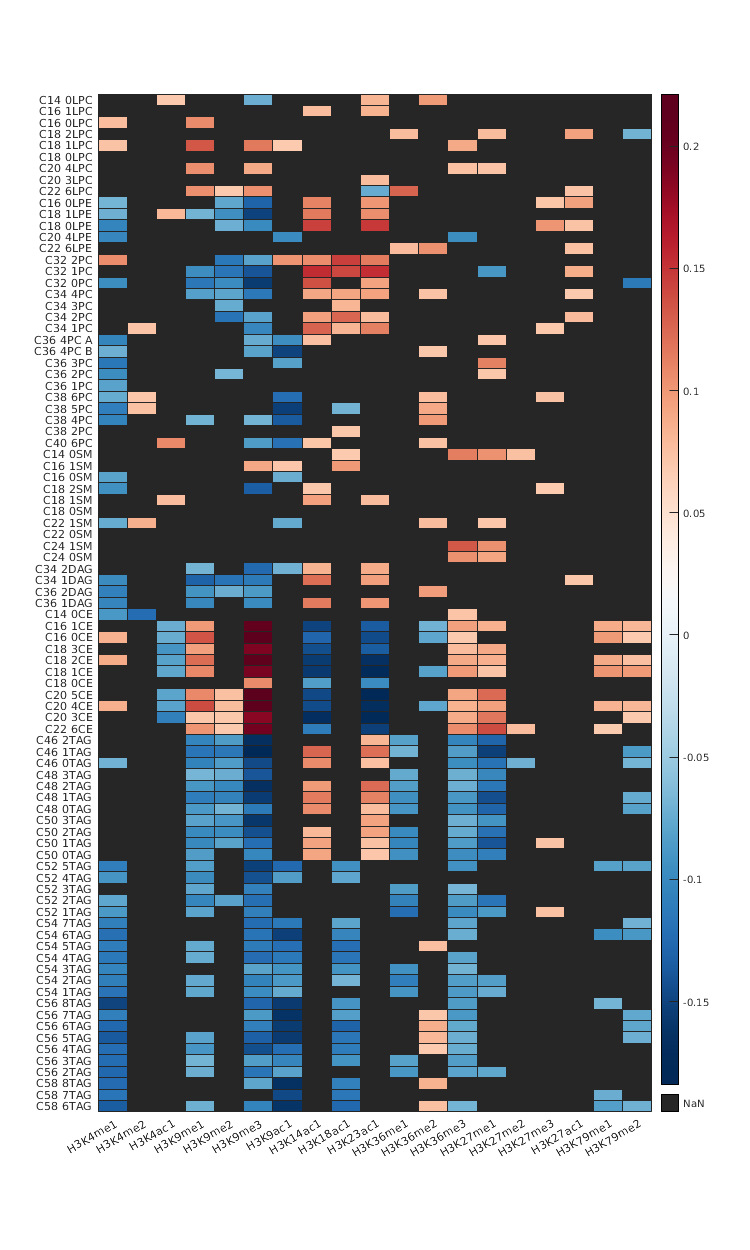

figure;
hm_obj = pcc_masked';
hm_obj = hm_obj(137:end, :);
heatmap(hm_obj, ...
        'colormap', redbluecmap, ...
        'XData', gcp_labels, ...
        'YData', met_labels(137:end));
set(findall(gcf,'-property','FontSize'),'FontSize',10);
set(gcf,'position',[0,0,750,1250]);

## Methylation and acetylation subsets

This analysis splits the metabolomics and GCP data into groups that will (hopefully) let us see biologically relevant trends in the data.

### Acetylation and Methylation Subsets

This analysis splits the histone markers by methylation and acetylation status. 

First, we'll create a temporary structure to hold all of the data.

tmp = pcc_masked';

Then we'll separate the acetylation and methylation markers.

ac_pos = contains(gcp_labels, 'ac1');

% Make datasets
ac_data = tmp(:, ac_pos);
me_data = tmp(:, ~ac_pos);

% Make histone marker labels
ac_labels = gcp_labels(ac_pos);
me_labels = gcp_labels(~ac_pos);

I think to simplify our analyses further, I need to split up the data between lipids and polar metabolites.

ac_lipids = ac_data(137:end, :);
me_lipids = me_data(137:end, :);
ac_polar = ac_data(1:136, :);
me_polar = me_data(1:136, :);

% Make metabolite labels
lipid_labels = met_labels(137:end);
polar_labels = met_labels(1:136);

First up is acetylation markers and lipids

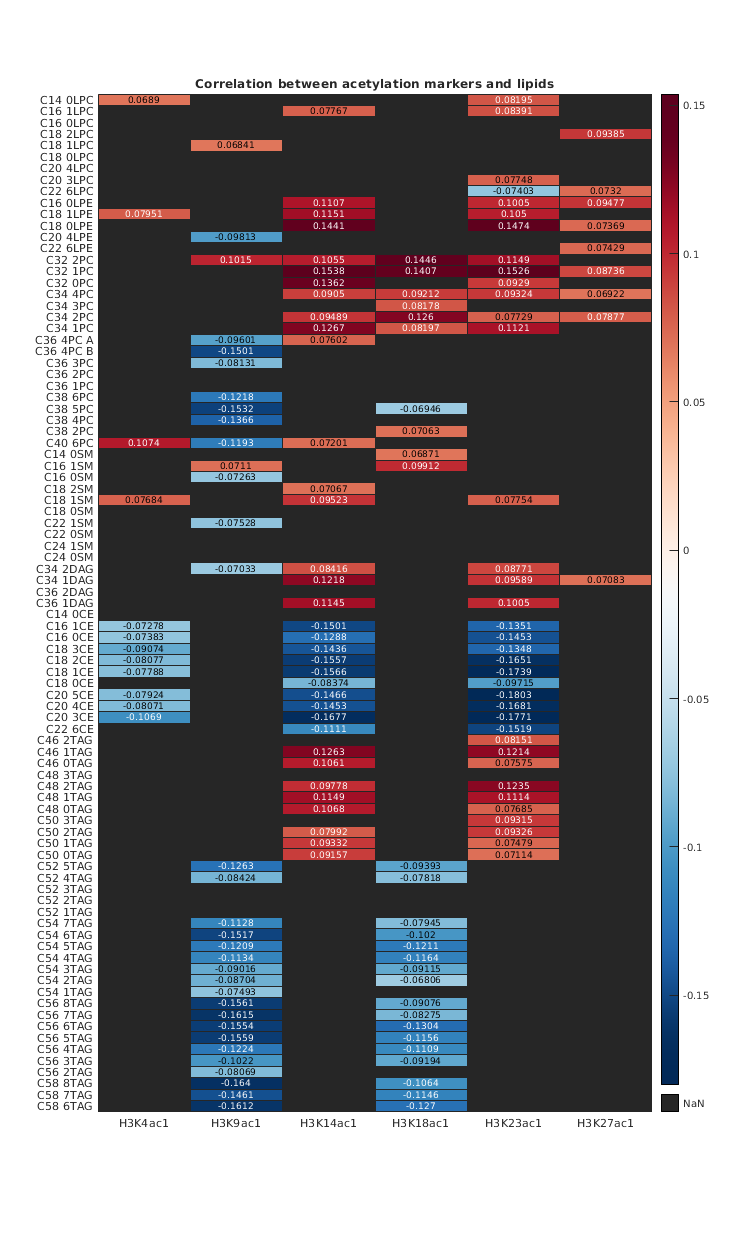

figure;
heatmap(ac_lipids, ...
        'colormap', redbluecmap, ...
        'XData', ac_labels, ...
        'YData', lipid_labels);
title('Correlation between acetylation markers and lipids');
set(findall(gcf,'-property','FontSize'),'FontSize',10);
set(gcf,'position',[0,0,750,1250]);

Next up is acetylation markers and polar metabolites.

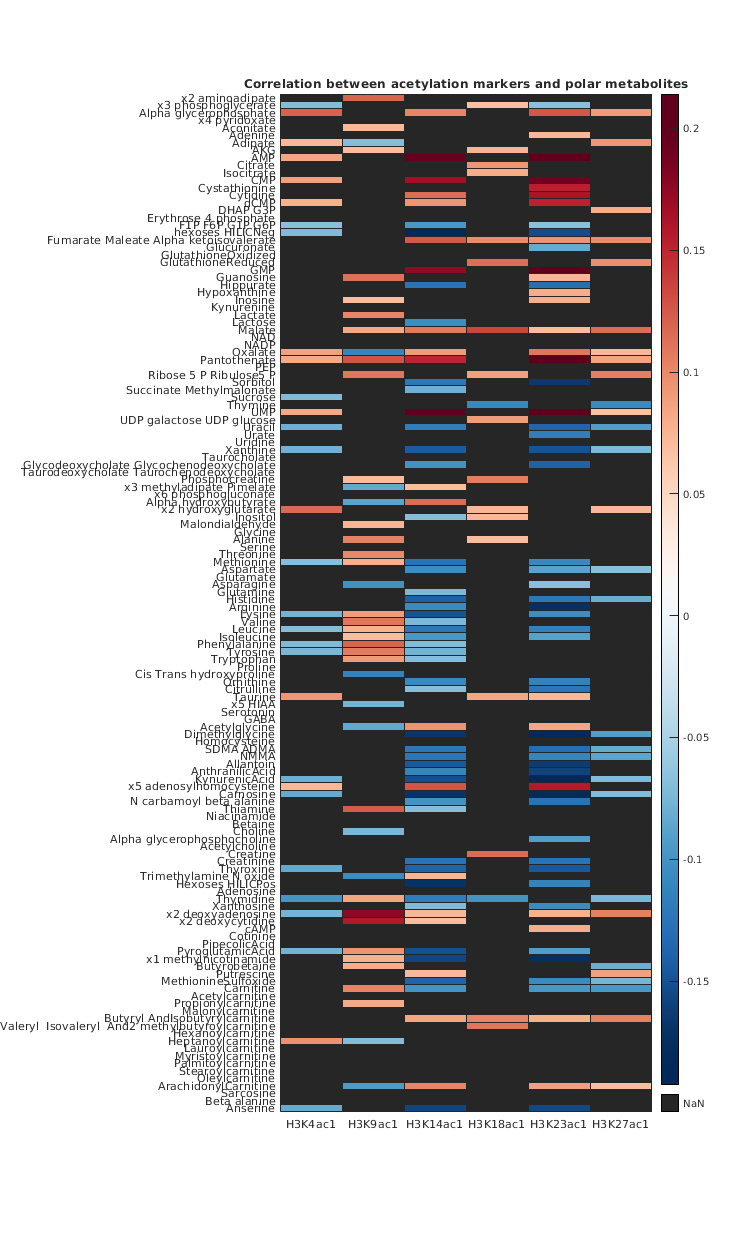

figure;
heatmap(ac_polar, ...
        'colormap', redbluecmap, ...
        'XData', ac_labels, ...
        'YData', polar_labels);
title('Correlation between acetylation markers and polar metabolites');
set(findall(gcf,'-property','FontSize'),'FontSize',10);
set(gcf,'position',[0,0,750,1250]);

Then we have methylation markers and lipids. 

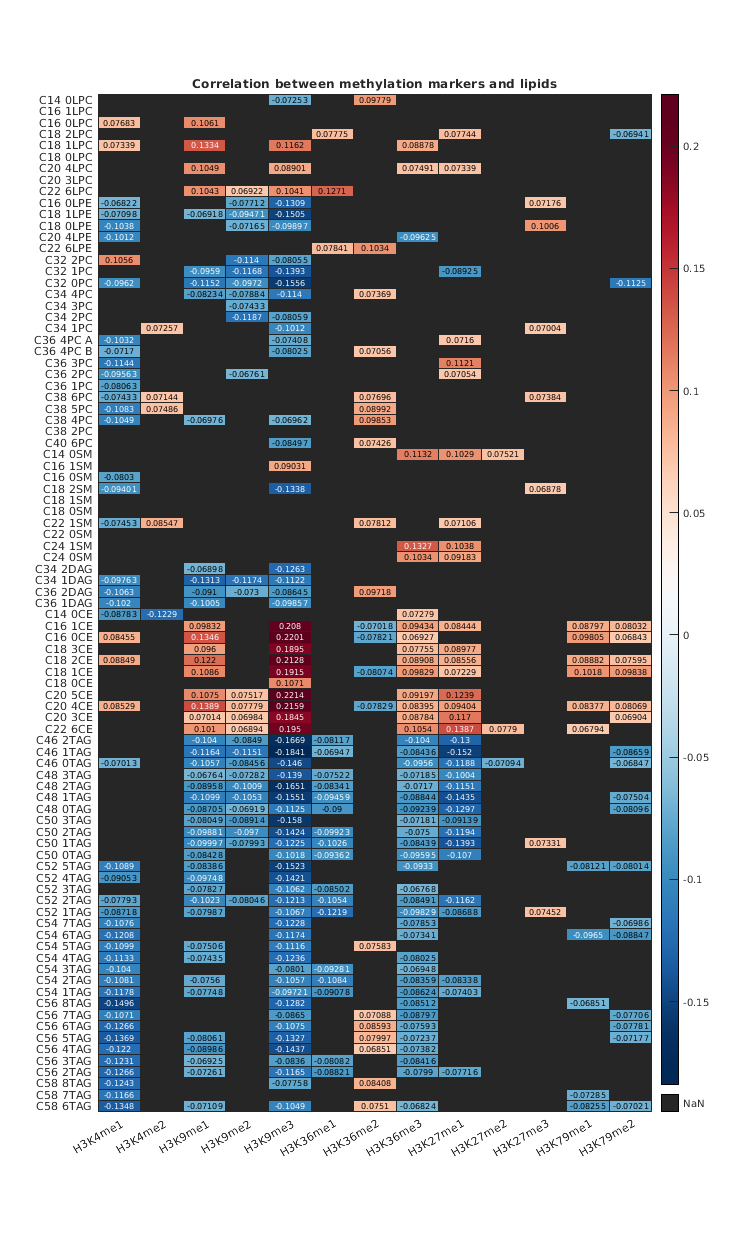

figure;
heatmap(me_lipids, ...
        'colormap', redbluecmap, ...
        'XData', me_labels, ...
        'YData', lipid_labels);
title('Correlation between methylation markers and lipids');
set(findall(gcf,'-property','FontSize'),'FontSize',10);
set(gcf,'position',[0,0,750,1250]);

Finally, we have methylation markers and polar metabolites. It's pretty hard to say anything definitively, other than the fact that H3K4me2, and H3K9 methylation markers have many more significant correlations with metabolites than other histone markers.

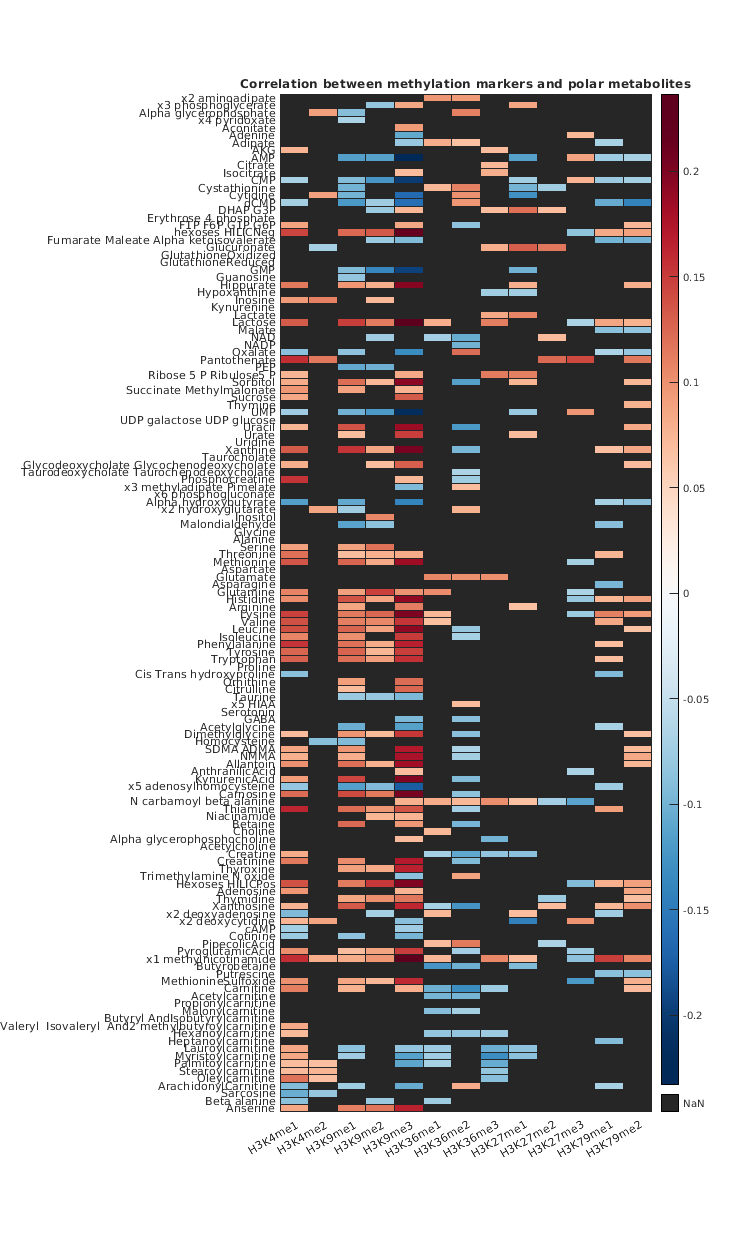

figure;
heatmap(me_polar, ...
        'colormap', redbluecmap, ...
        'XData', me_labels, ...
        'YData', polar_labels);
title('Correlation between methylation markers and polar metabolites');
set(findall(gcf,'-property','FontSize'),'FontSize',10);
set(gcf,'position',[0,0,750,1250]);

### Metabolite Subsets

Let's now partition the dataset based on both histone methylation/acetylation markers, and different metabolite subsets.

#### Amino acids

This is the correlation between acetylation and methylation markers, and amino acids. The takeaways:

- For the most part, H3K9ac seems to be positively correlated with amino acid levels, while other acetylation makers.

- H3K4me1 and H3K9 methylation are positively correlated with amino acid levels. 

- There is some positive correlation with H3K79 methylation and amino acid levels.

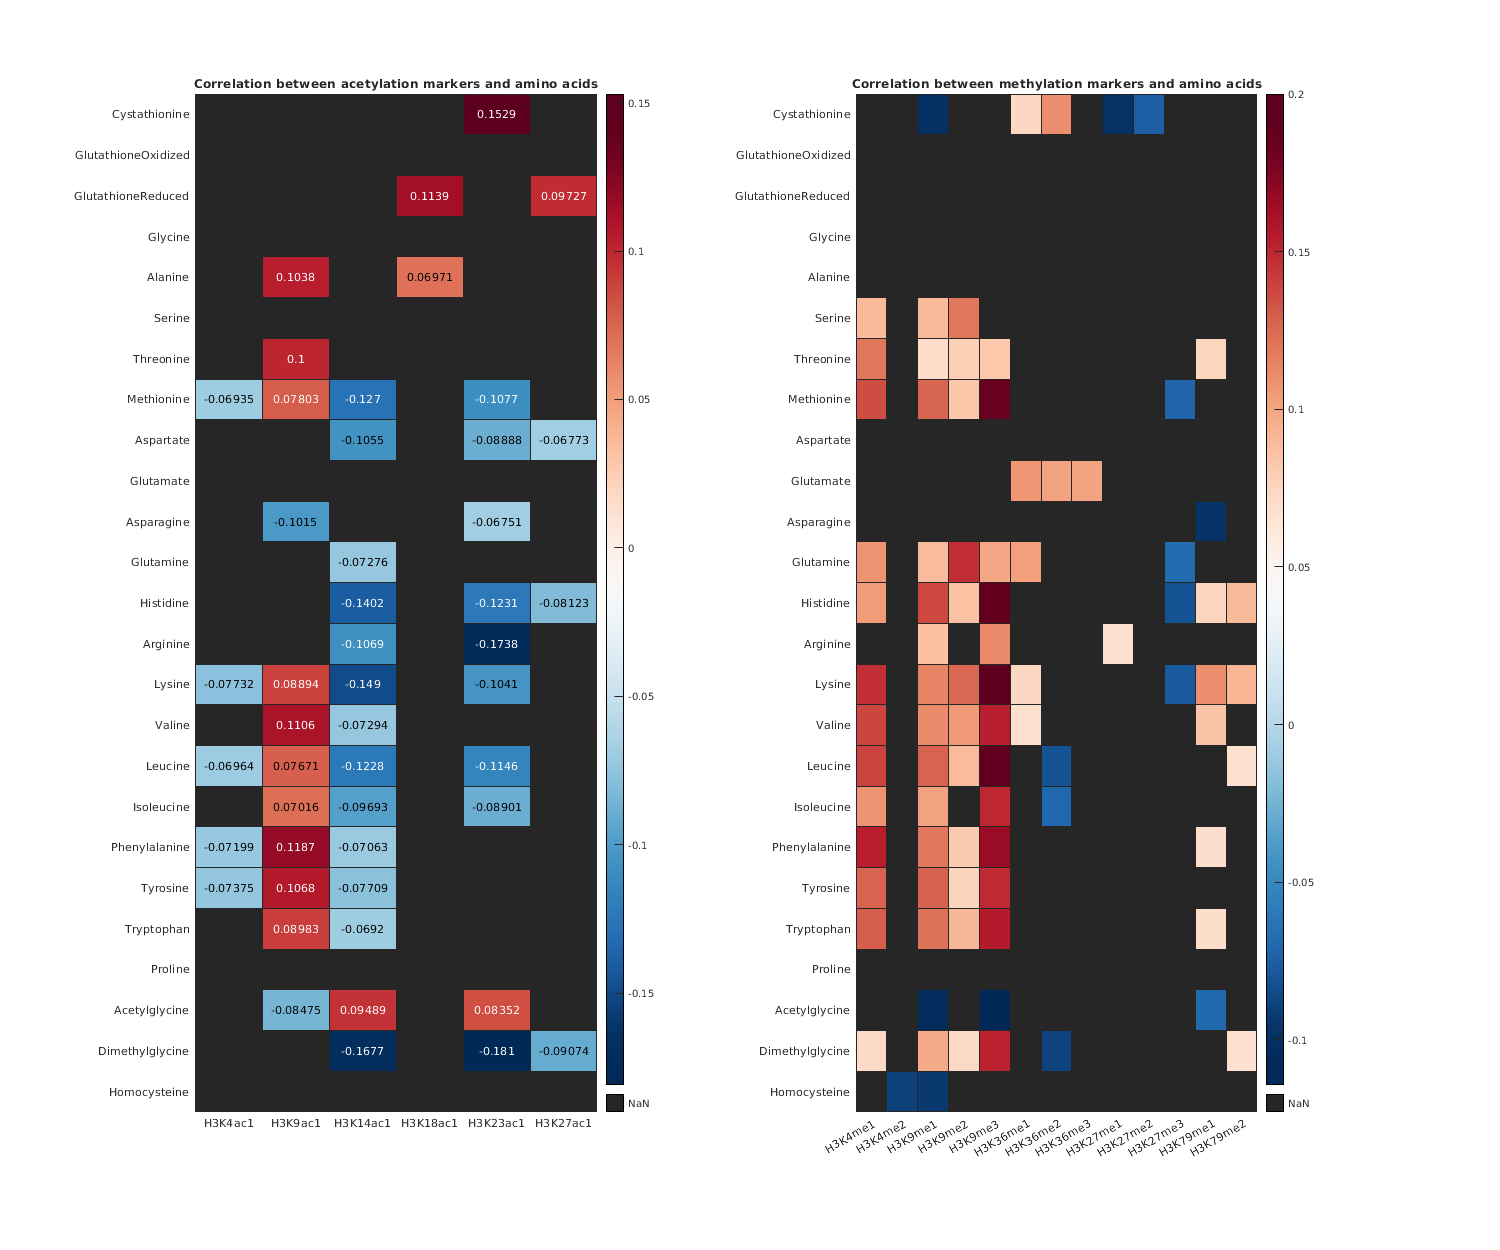

aa_pos = [13, 22, 23, 59:77, 85:87];
ac_aa = ac_data(aa_pos, :);
me_aa = me_data(aa_pos, :);

% Make metabolite labels
aa_labels = met_labels(aa_pos);

figure;
subplot(1, 2, 1);
heatmap(ac_aa, ...
        'colormap', redbluecmap, ...
        'XData', ac_labels, ...
        'YData', aa_labels);
title('Correlation between acetylation markers and amino acids');
subplot(1, 2, 2);
heatmap(me_aa, ...
        'colormap', redbluecmap, ...
        'XData', me_labels, ...
        'YData', aa_labels);
title('Correlation between methylation markers and amino acids');
set(findall(gcf,'-property','FontSize'),'FontSize',10);
set(gcf,'position',[0,0,1500,1250]);

#### Nucleic acids

This is the correlation between acetylation and methylation markers, and nucleic acid molecules. The takeaways:

- For acetylation, G, C, and U metabolism are positively correlated, while A is mixed and T is negatively correlated. Why??

- For methylation, we are basically seeing the opposite??

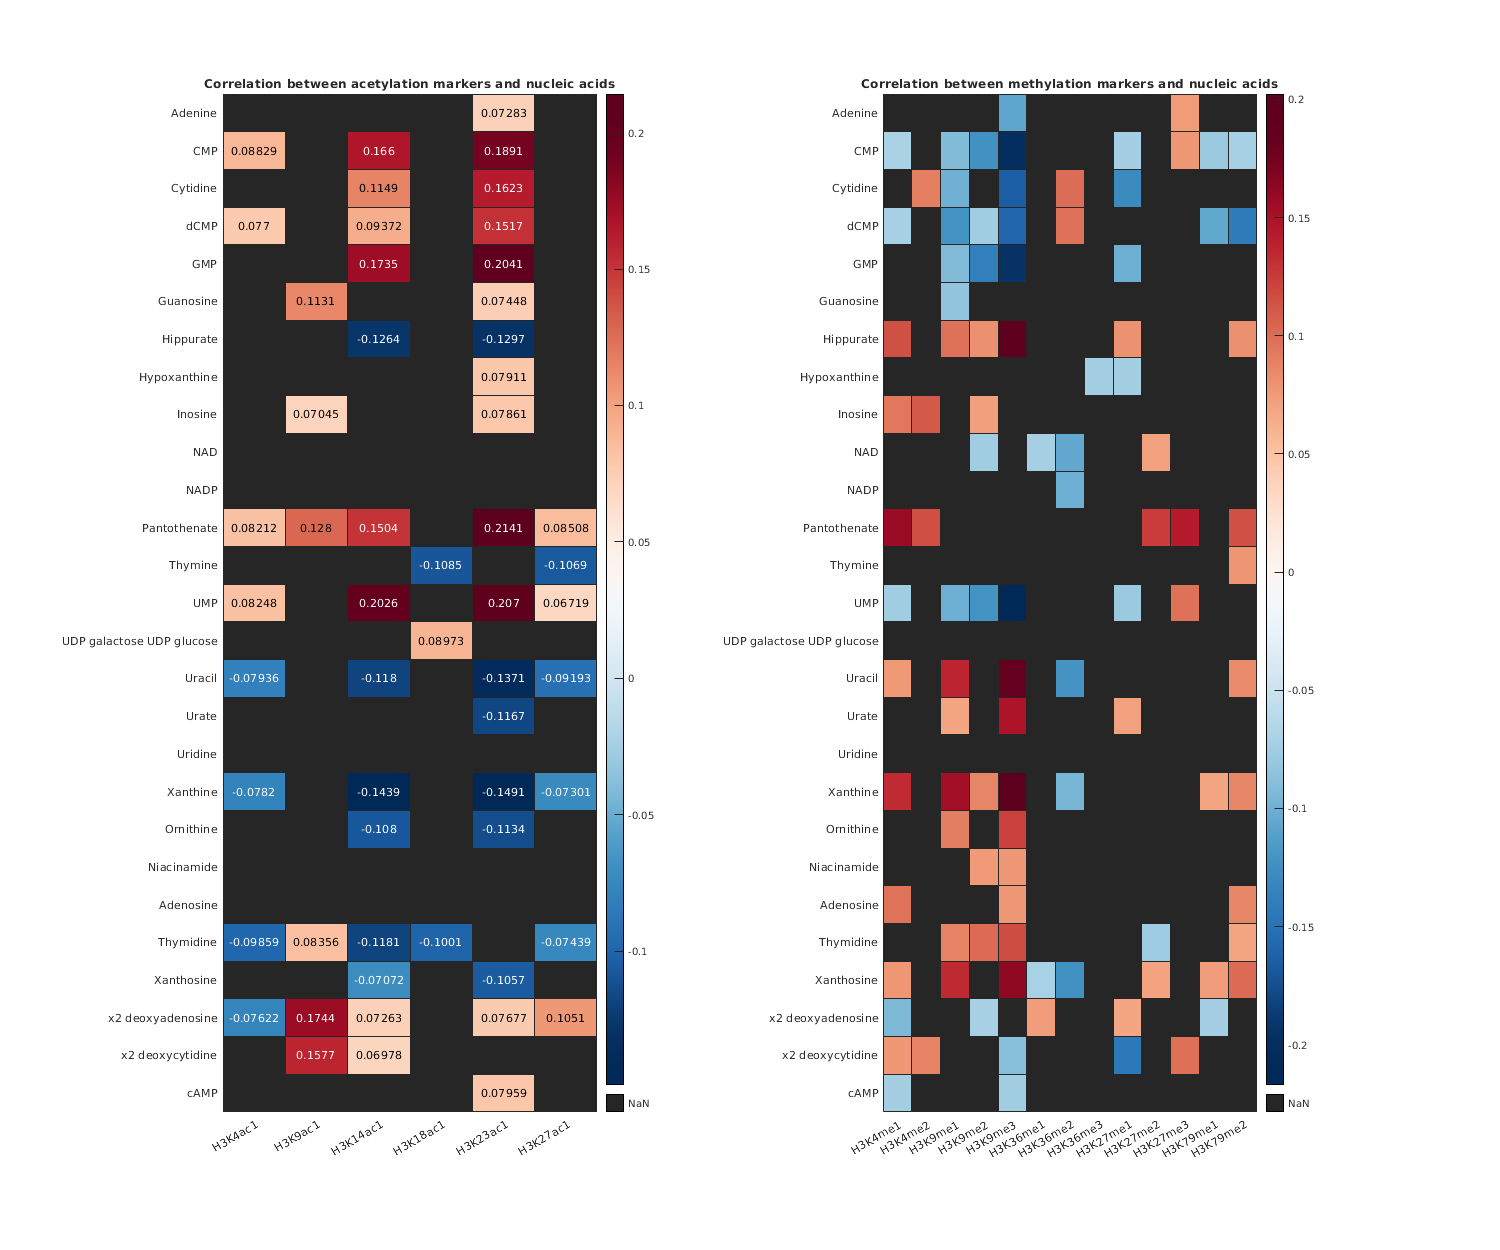

nuc_pos = [6, 12, 14, 15, 24:28, 33:34, 36, 42:48, 79, 97, 107:112];
ac_nuc = ac_data(nuc_pos, :);
me_nuc = me_data(nuc_pos, :);

% Make metabolite labels
nuc_labels = met_labels(nuc_pos);

figure;
subplot(1, 2, 1);
heatmap(ac_nuc, ...
        'colormap', redbluecmap, ...
        'XData', ac_labels, ...
        'YData', nuc_labels);
title('Correlation between acetylation markers and nucleic acids');
subplot(1, 2, 2);
heatmap(me_nuc, ...
        'colormap', redbluecmap, ...
        'XData', me_labels, ...
        'YData', nuc_labels);
title('Correlation between methylation markers and nucleic acids');
set(findall(gcf,'-property','FontSize'),'FontSize',10);
set(gcf,'position',[0,0,1500,1250]);

#### Central metabolism metabolites

This is the correlation between acetylation and methylation markers, and central metabolism metabolites from Glycolysis and TCA cycle. The takeaways:

- For the most part, it's a mixed bag. However, it looks like fumarate and malate have opposing correlations overall between acetylation and methylation.

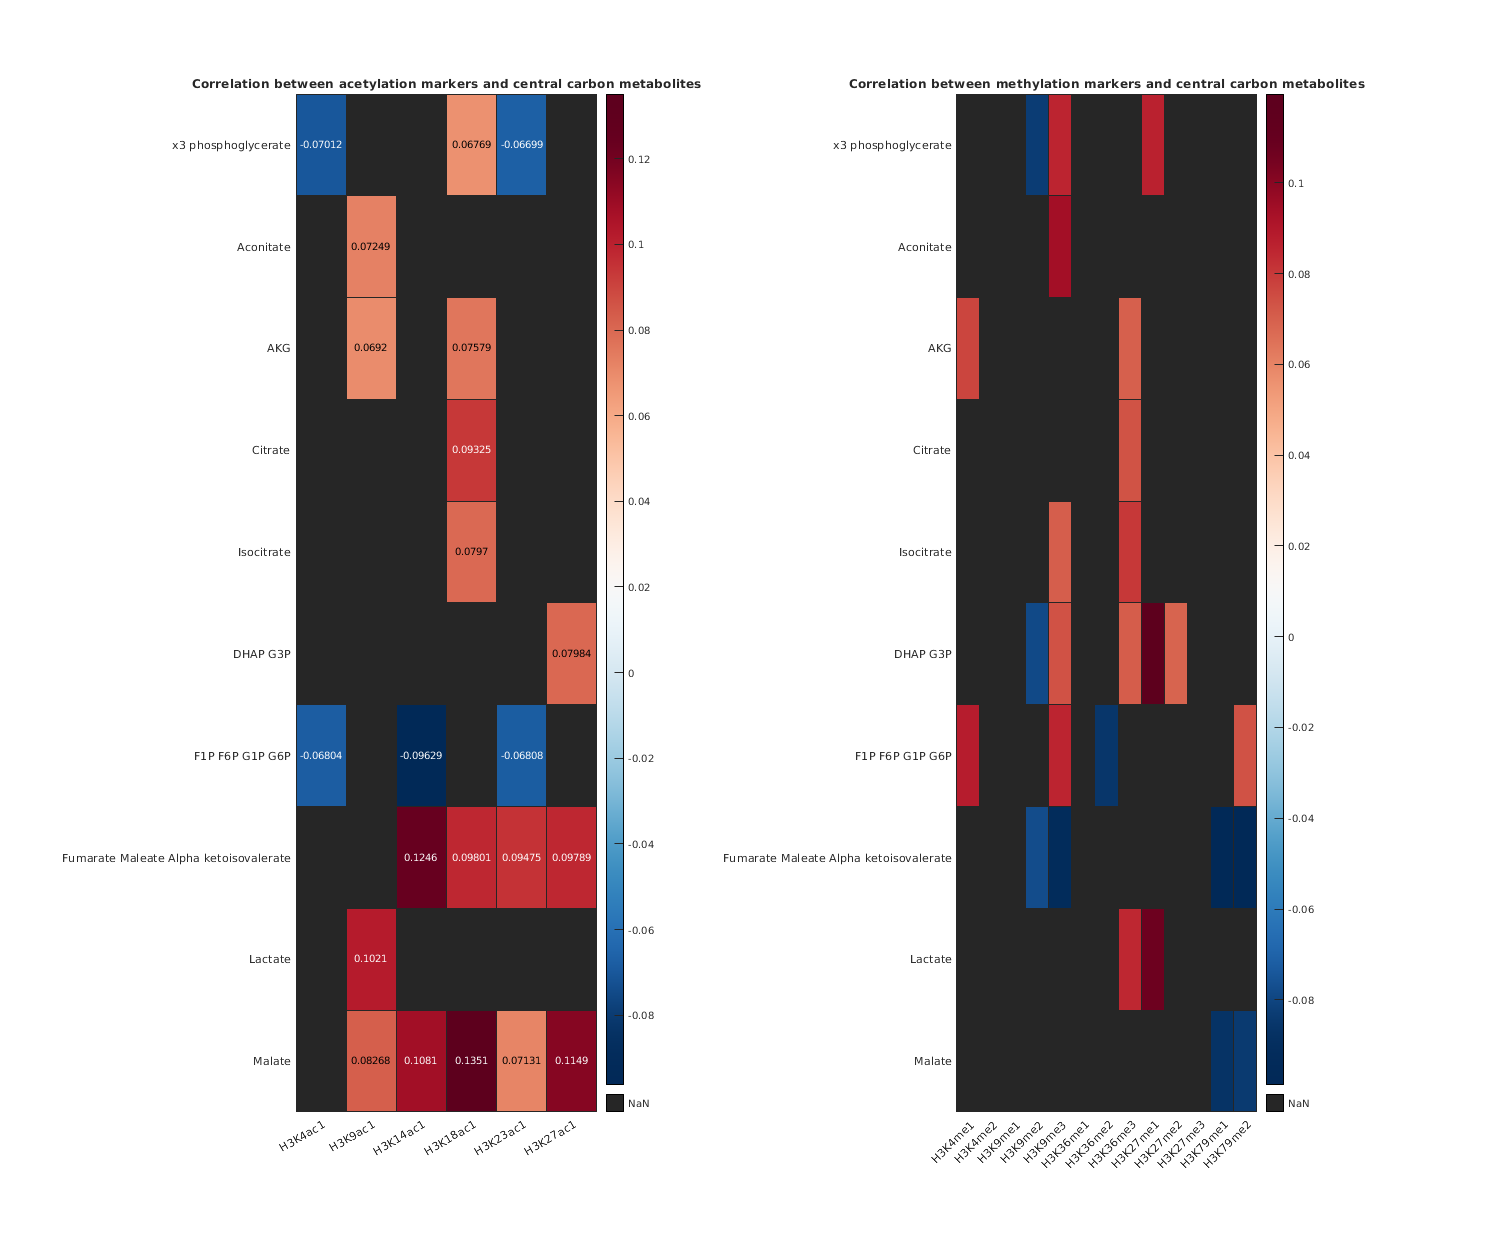

cc_pos = [2, 5, 8, 10, 11, 16, 18, 20, 30, 32];
ac_cc = ac_data(cc_pos, :);
me_cc = me_data(cc_pos, :);

% Make metabolite labels
cc_labels = met_labels(cc_pos);

figure;
subplot(1, 2, 1);
heatmap(ac_cc, ...
        'colormap', redbluecmap, ...
        'XData', ac_labels, ...
        'YData', cc_labels);
title('Correlation between acetylation markers and central carbon metabolites');
subplot(1, 2, 2);
heatmap(me_cc, ...
        'colormap', redbluecmap, ...
        'XData', me_labels, ...
        'YData', cc_labels);
title('Correlation between methylation markers and central carbon metabolites');
set(findall(gcf,'-property','FontSize'),'FontSize',10);
set(gcf,'position',[0,0,1500,1250]);

Tissue profiles